# Motor control (evaluated assignment)

## Introduction

Following cascade control structure will be used for motor control in order to achieve fast tracking and strong disturbance rejection.

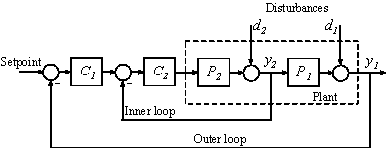

Goal of this exercise is to optimize (tune) parameters of two sets of controllers. Inner loop controller will be responsible for current control and outter loop controller will handle the speed tracking itself.

## Controller tuning procedure

Tuning of the conroller parameters is accomplished in two separate steps:

- Optimization of current loop $H_{\infty \;}$ controller

- Optimization of outer speeed loop $H_{\infty \;}$ controler

Performance and stability requirements are again specified using wieghting functions connected to the specific points of the control diagram (see previous exercise for details).

## Task 1

Optimize current and speed control loops for the following model of DC motor:


$$\dot{x}= \left[\matrix{ -\frac{R}{L} & -\frac{K_b}{L} \cr \frac{K_b}{J} & -\frac{K_f}{J}} \right]x+\left[\matrix{ \frac{1}{L}  \cr 0}\right]u$$



$$y= \left[\matrix{ 1 & 0 \cr 0 & 1} \right]x+\left[\matrix{ 0  \cr 0}\right]u$$


Where$x_1$ is the stator current, $x_2$ is the rotor speed and *u*is the stator voltage.

R = 2.5;
L = 0.00045;
J = 0.0000072;
Km = 0.052;
Kb = 0.052;
Kf = 0.000048;

A = [-R/L -Kb/L;
     Km/J -Kf/J];
B = [1/L; 0];
C = [1 0;
     0 1];
D = [0;0];

G = ss(A,B,C,D);
G.InputName = 'u';
G.OutputName = {'i','w'};
G.StateName = {'Current';'Speed'};

## Current loop:

- Modify the C matrix to contain just the current output

C = [0 1]% FILL IN

C =      0     1


D = 0% FILL IN

D = 0

% plant creation and i/o definitions needs to be repeated
G = ss(A,B,C,D);
G.InputName = 'u';
G.OutputName = {'i'};

- Create sensitivity and complementary sensitivity weights, set all the A, M, w parameters accordingly (you can use makeweight function)

%% Proudova smycka
% current feedback loop
% Vaha pro S
% Sensitivity weight
Api = 1/100;       
Mpi = 2 % FILL IN           

Mpi = 2

wpi = 100;            

Wpi = makeweight(1/Api,wpi,1/Mpi);% FILL IN                  
Wpi.InputName = "ei"; % FILL IN
Wpi.OutputName = "zpi"; % FILL IN


% Vaha pro T
% Complementary sensitivity weight
Ati = 1.01;                          
Mti = 1/10 % FILL IN                            

Mti = 0.1000

wti = 500;

Wti = makeweight(1/Ati,wti,1/Mti);

Wti.InputName = "i"; % FILL IN
Wti.OutputName = "zti"; % FILL IN

- Create subtraction block (you can use sumblk function)

subi = sumblk('ei = ri-i');% FILL IN

- Check that the i/o names for the plant G (with modified C) and both weights Wpi, Wti are according to the following diagram:

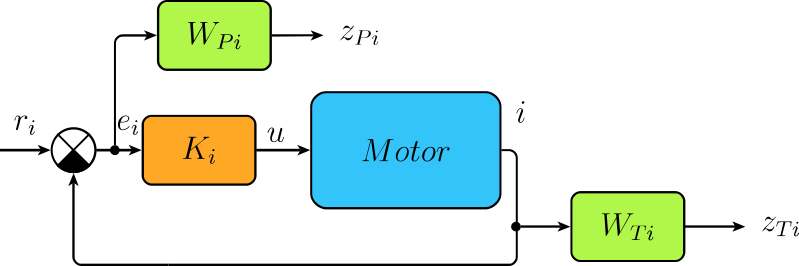

- Connect **all** the blocks for the current loop using the connect function, don't forget that $u$ and $e_i$ need to be the **last** in the i/o list!!!

sysi = connect(G,Wti,Wpi,subi,{'ri','u'},{'zpi';'zti';'ei'});% FILL IN

- Run the following commands to optimize the controller according to the selected weights:

nmeas = 1;
ncon = 1; 

[Ki,CL,gam] = hinfsyn(sysi,nmeas,ncon);

- Name the controller i/o


Ki.InputName = "ei"; % FILL IN
Ki.OutputName = "u"; % FILL IN

- Construct sensitivity and complementary sensitivity functions and check the bounds specified by inverse of individual weights in frequency domain (use the connect function to make connections, omit weights from the diagram)

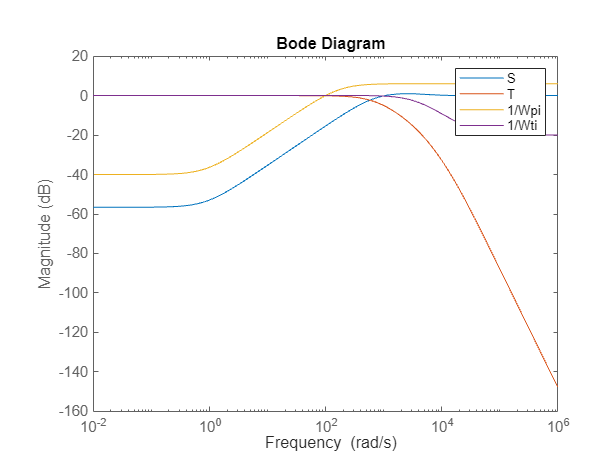

S = connect(G,Ki,subi,{'ri'},{'ei'});% FILL IN
T = connect(G,Ki,subi,{'ri'},{'i'}); %FILL IN 

figure(1)
bodemag(S,T,1/Wpi,1/Wti)
legend("S","T","1/Wpi","1/Wti");

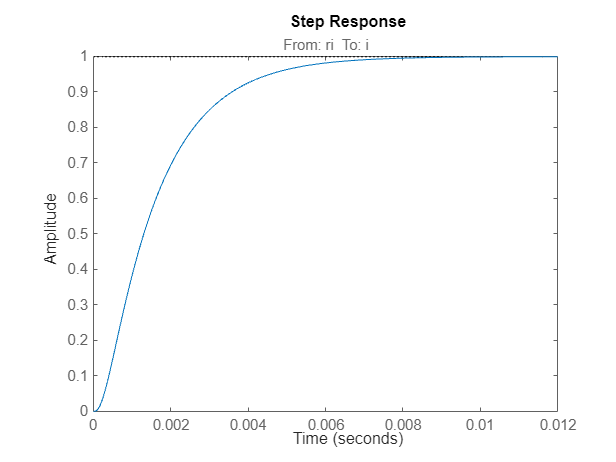


figure(2)
step(T)


f = max(2*abs(eig(S.a)))

f = 6.4870e+04

## Speed loop:

- Modify the C matrix to contain both outputs, update the plant G with new C

C = [1 0;
     0 1] % FILL IN

C =      1     0
     0     1


D = 0 % FILL IN

D = 0

% plant creation and i/o definitions needs to be repeated
G = ss(A,B,C,D);
G.InputName = 'u';
G.OutputName = {'i','w'};

- Create sensitivity and complementary sensitivity weights, set all the A, M parameters accordingly, set w at **least 10x slower** compared to the current loop

% S weight
Apw = 1/100;       
Mpw = 8; % FILL IN           
wpw = 1;           

Wpw = makeweight(1/Apw,wpw,1/Mpw); % FILL IN                  
Wpw.InputName = "ew"; % FILL IN
Wpw.OutputName = "zpw"; % FILL IN

% T weight
Atw = 1.01;                          
Mtw = 1/50; % FILL IN                             
wtw = 50;

Wtw = makeweight(1/Atw,wtw,1/Mtw);
Wtw.InputName = "w"; % FILL IN
Wtw.OutputName = "ztw"; % FILL IN

- Create subtraction block for both current and speed loops, you can re-use the current subtraction **subi**

subw = sumblk("ew = rw - w"); % FILL IN

- Check that the i/o names for the optimized controller Ki, plant G (with updated C for both inputs) and both weights Wpw, Wtw according to the following diagram:

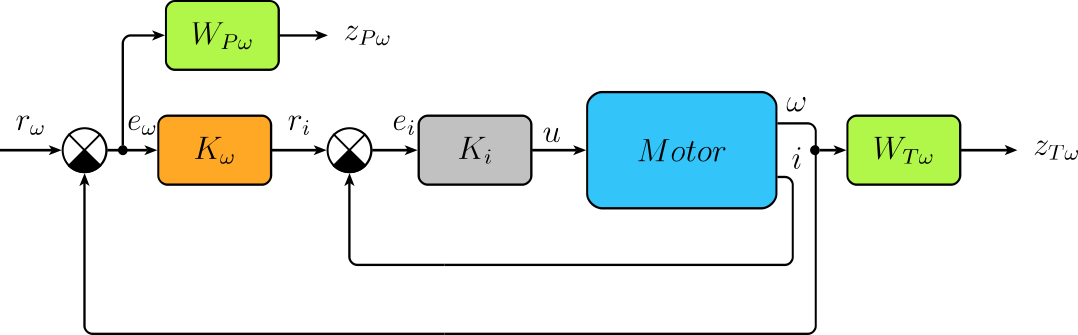

- Connect **all** the blocks for the speed loop using the connect function **(don't forget to include the Kw controller)**, don't forget that $r_i$ and $e_w$ need to be the **last** in the i/o list!!!

Kw = ltiblock.pid('Kw','pi'); 
Kw.InputName = 'ew';
Kw.OutputName = 'ri';

sysw = connect(G,subw,subi,Kw,Ki,Wpw,Wtw,{'rw','ri'},{'zpw','ztw','ew'});% FILL IN

- Run the following commands to optimize the controller according to the selected weights:

nmeas = 1;
ncon = 1; 

[Kw,CL,gam] = hinfsyn(sysw,nmeas,ncon);

- Name the controllers i/o:

Kw.InputName = "ew"; % FILL IN
Kw.OutputName = "ri"; % FILL IN

- Construct sensitivity and complementary sensitivity functions and check the bounds specified by inverse of individual weights in frequency domain (use the connect function to make connections, omit weights from the diagram)

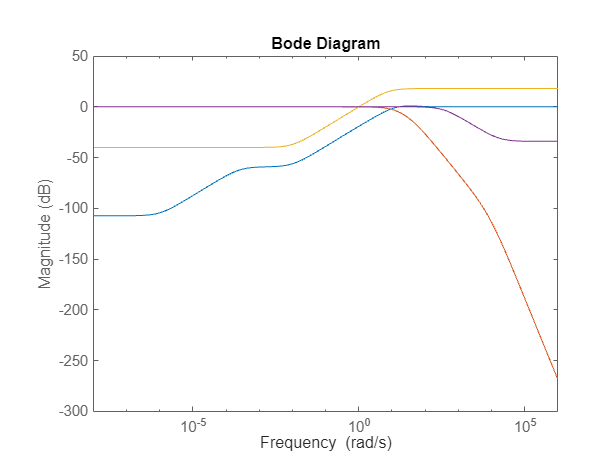

S = connect(G,subw,subi,Kw,Ki,{'rw'},{'ew'}); % FILL IN
T = connect(G,subw,subi,Kw,Ki,{'rw'},{'w'}); % FILL IN

figure(3)
bodemag(S,T,1/Wpw,1/Wtw)

- Check the final step response of the result

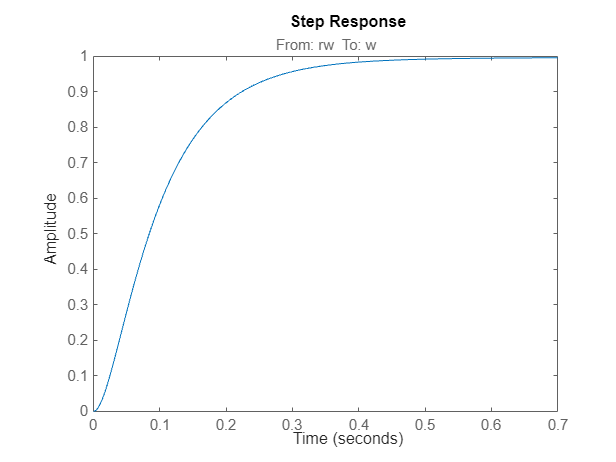

figure(4)
step(T)


f = max(2*abs(eig(S.a)))

f = 6.4954e+04

disp(join(["Sampling time =",string(f),"x2"]))

Sampling time = 64954.1597 x2
